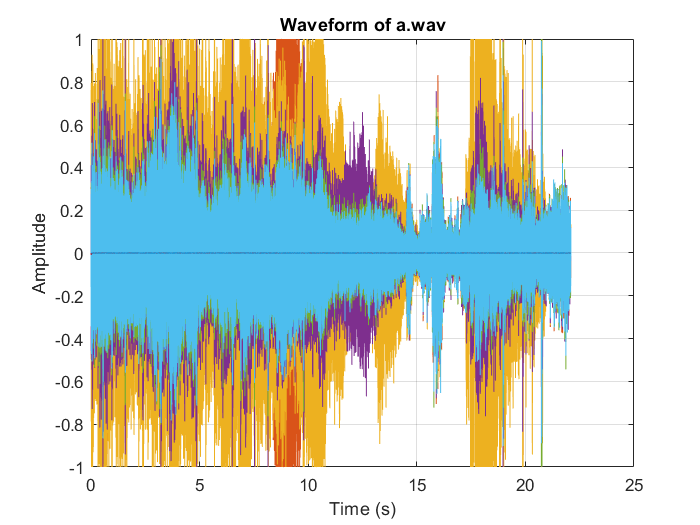

% Read the .wav file
[file, path] = uigetfile('a.wav', 'C:\Users\Raveen\Audio-Signal-Processing---Respeaker-Microphone-Array');
filePath = fullfile(path, file);
[audioData, sampleRate] = audioread(filePath);

% Create a time vector
timeVector = (0:length(audioData)-1) / sampleRate;

% Plot the audio waveform
figure;
plot(timeVector, audioData);
xlabel('Time (s)');
ylabel('Amplitude');
title(['Waveform of ', file]);
grid on;


% Frequency Domain Plot
N = length(audioData);                  % Number of samples
Y = fft(audioData);                     % Perform FFT
f = (0:N-1) * (sampleRate / N);         % Frequency vector
magnitude = abs(Y) / N;                 % Magnitude spectrum

% Plot the positive frequencies only
subplot(2,1,2);
plot(f(1:N/2), magnitude(1:N/2));       % Plot up to Nyquist frequency

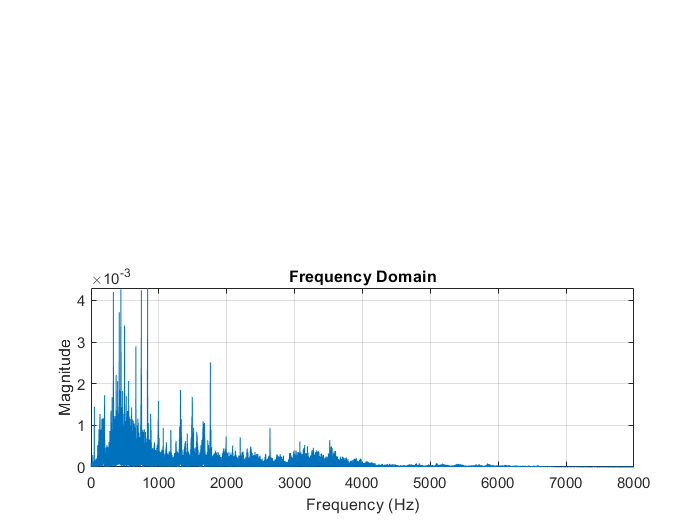

xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Frequency Domain');
grid on;